# Настройка регулятора

## Параметры системы

m = 0.8;
J_xx = 400;
J_yy = 1;
J_zz = 400;
l = 400;
k_f = 6.11 * 10^(-8);
g = 9.81;
m_k = pi;
alpha_0 = 0;
alpha_max = 16;
S = 0.005;
p = 1.225;
k = 1;
k_Y = m_k * S * p;
k_X = 0.1;

## Целевые значения

% Целевые координаты
x_0 = 0;
y_0 = 0;
z_0 = 0;

x_des = 10;
y_des = 0.5;
z_des = 0.5;

time = 1;

x_dot_min = sqrt((m * g) / (alpha_max * k_Y));

% Если хотим направить перед объекта в определенную сторону
%psi_des = 0;
% Если хотим направить перед объекта в сторону целевых координат
%psi_des = atan2(y_des, x_des);

## Параметры регуляторов

### Вертикальная тяга

ver.k_p_x = 0.1711;
ver.k_v_x = 13.0992;

ver.k_p_y = 16.9834;
ver.k_v_y = 9.7161;

ver.k_p_z = 50.6283;
ver.k_v_z = 10.1172;

ver.k_p_fi = 1.9589e+03;
ver.k_v_fi = 12.1764;

ver.k_p_theta = 858.1094;
ver.k_v_theta = 19.7473;

ver.k_p_psi = 89.6168;
ver.k_v_psi = 78.7648;

## Горизонтальная тяга

k_p_x = 3.0097;
k_v_x = 0.6232;

k_p_y = 1.9177;
k_v_y = 1.0836;

k_p_z = 2.6815;
k_v_z = 1.1762;

k_p_fi = 3.9452;
k_v_fi = 1.1167;

k_p_theta = 1.1343;
k_v_theta = 0.7855;

k_p_psi = 2.5287;
k_v_psi = 0.9883;

## Спиральная траектория

z_1 = [0:0.1:2*pi];
x_1 = cos(z_1);
y_1 = sin(z_1);
%plot3(x_1, y_1, z_1);

%x_2 = [0:0.005:2*pi];
%y_2 = sin(x_2);
%x_2 = x_2 * 3 / (2*pi) + 1;
%z_2 = zeros(size(x_2)) + 2*pi;
%plot3(x_2, y_2, z_2);

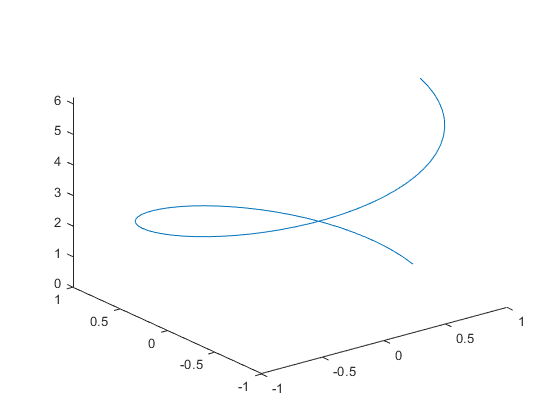

%z_3 = [2*pi:-0.005:0];
%x_3 = -cos(z_3) + 2;
%y_3 = -sin(z_3);
%plot3(x_3, y_3, z_3);

Z = [z_1];
X = [x_1];
Y = [y_1];

plot3(X, Y, Z);

s = size(X);
T = [0:s(2) - 1] / s(2) * 50;

map = [T; X; Y; Z];

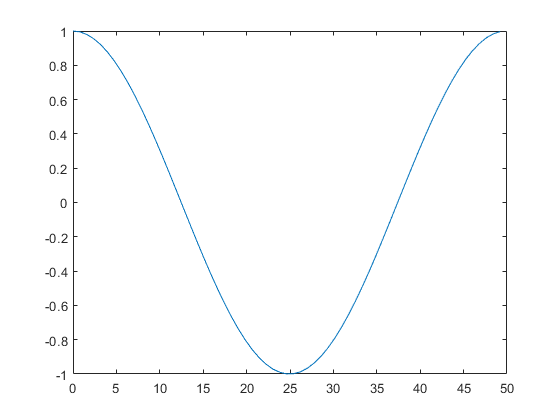

plot(T, X)

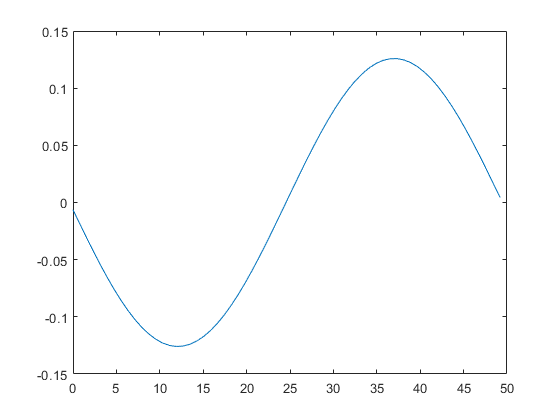

dot_X = (X(2:end) - X(1:end - 1)) ./ (T(2:end) - T(1:end - 1));
dot_X(end + 1) = dot_X(end) + (dot_X(end) - dot_X(end - 1));
plot(T, dot_X)

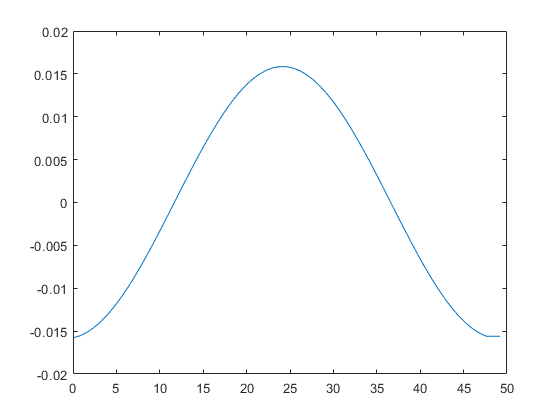

ddot_X = (dot_X(2:end) - dot_X(1:end - 1)) ./ (T(2:end) - T(1:end - 1));
ddot_X(end + 1) = ddot_X(end) + (ddot_X(end) - ddot_X(end - 1));
plot(T, ddot_X)